# Template of Manipulator Short project: Skull tumor surgery

### **OPTION 2**

### **Grup 11- Estudiants:**

- **Pol Casacuberta Gil**

- **Marta Granero i Martí**

**Link: **https://drive.matlab.com/sharing/b8a7f88a-dcb6-4c09-a328-ba6c7e737807

I spect: 1) Pdf file, 2) Videos demostrating your successful task and your mlx file.

Notes. For better undestanding you can split the videos in the meaninful task.

Remember use the options of serial/link plot: 

'workspace' for centering in the surgery task

'zoom' ...  nice puma ratio aspect

'trail'  .. to see the trajectory

etc..

See all at:

>> help SerialLink/plot

## The Robotic environment (10%)

Think that later on the enviroment will move to any place in a Univers Reference Frame {U}

Use: 'c = uisetcolor' to chose your prefered colors

### Operating table.

 It can be raised, lowered, and tilted in any direction, and an  auxiliary table for the tools. Define: Vertices and Faces and use  'patch'  functions to model it. See help patch to find and example.

Think that later on the enviroment will move to any place in a Univers Reference Frame {U}

**Expected results**

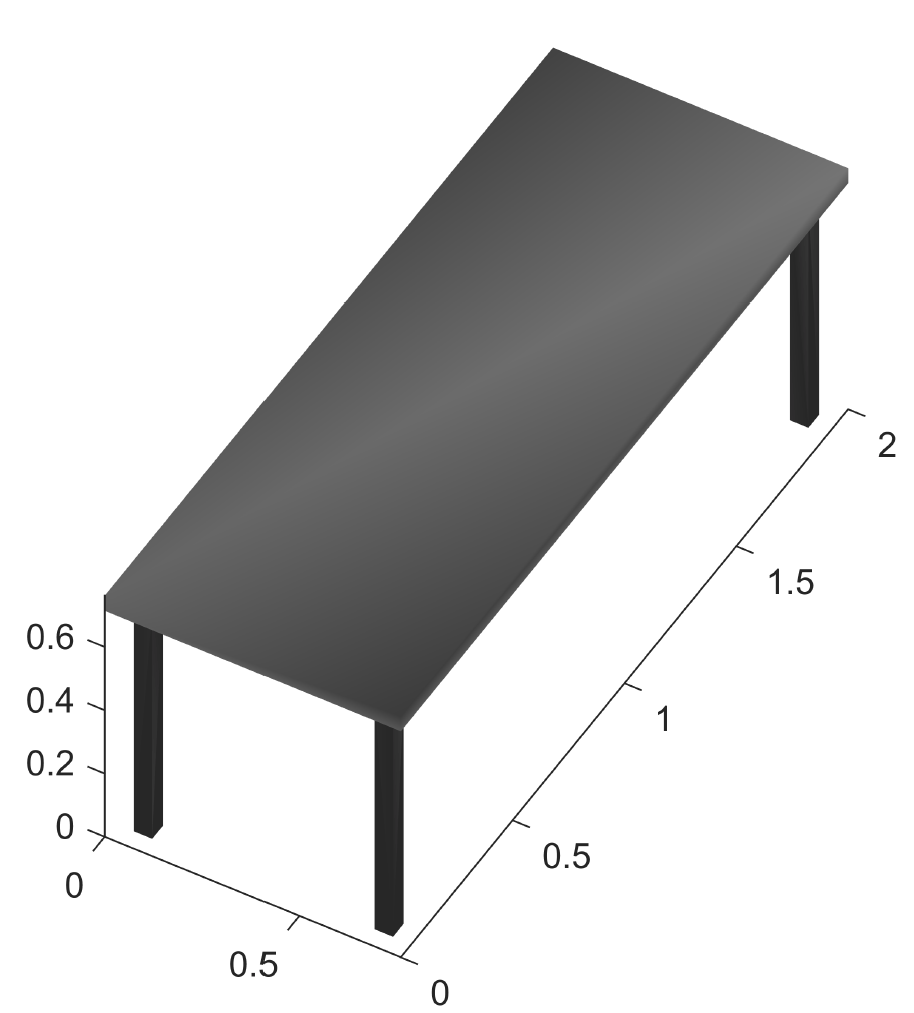

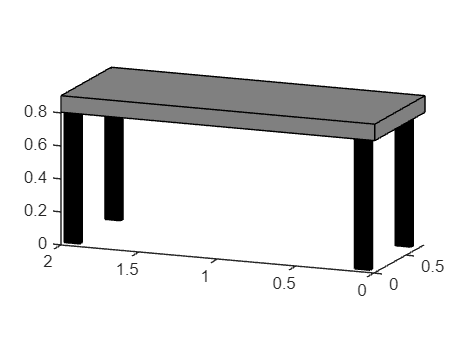

clear
close all
clf
v = [-20 -8 5];
[caz,cel] = view(v);

% Define the dimensions of the flat board
board_width = 0.8; % width of the board (y)
board_length = 2; % length of the board (x)
board_thickness = 0.1; % thickness of the board

% Define the vertices of the board
v = [0, 0, 0;  % bottom left corner
     board_width, 0, 0; % bottom right corner
     board_width, board_length, 0; % top right corner
     0, board_length, 0; % top left corner
     0, 0, board_thickness; % bottom left corner of top surface
     board_width, 0, board_thickness; % bottom right corner of top surface
     board_width, board_length, board_thickness; % top right corner of top surface
     0, board_length, board_thickness]; % top left corner of top surface

% Define the faces of the board
f = [1, 2, 6, 5; % bottom face
     2, 3, 7, 6; % right face
     3, 4, 8, 7; % top face
     4, 1, 5, 8; % left face
     5, 6, 7, 8; % top surface
     1, 2, 3, 4]; % bottom surface
T_mesa_U = transl(0,0, 0.8);

v_pata = [0.05 0 0; 0 0.05 0; 0 0 8]*v'; % We scale the table in such a way we get a leg of the table
v_pata1 = v_pata + [0.05 0.05 -0.8]';
v_pata2 = v_pata + [ 0.70 0.05 -0.8]';
v_pata3 = v_pata + [ 0.05 1.90 -0.8]';
v_pata4 = v_pata + [ 0.70 1.90 -0.8]';

v_pata1 = v_pata1';
v_pata2 = v_pata2';
v_pata3 = v_pata3';
v_pata4 = v_pata4';

v_pata1(:,4) = 1;
v_pata2(:,4) = 1;
v_pata3(:,4) = 1;
v_pata4(:,4) = 1;

v_pata1 = T_mesa_U*v_pata1';
v_pata1 = v_pata1(1:3,:)';
v_pata2 = T_mesa_U*v_pata2';
v_pata2 = v_pata2(1:3,:)';
v_pata3 = T_mesa_U*v_pata3';
v_pata3 = v_pata3(1:3,:)';
v_pata4 = T_mesa_U*v_pata4';
v_pata4 = v_pata4(1:3,:)';

v(:,4) = 1;
v = v';

v = T_mesa_U *v;
% Plot the flat board
v = v';
patch('Vertices', v(:,1:3), 'Faces', f, 'FaceColor', [0.5, 0.5, 0.5]);

patch('Vertices',v_pata1(:,1:3),'Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.0 0.0 0.0])
patch('Vertices',v_pata2,'Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.0 0.0 0.0])
patch('Vertices',v_pata3,'Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.0 0.0 0.0])
patch('Vertices',v_pata4,'Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.0 0.0 0.0])

axis equal; hold on;

v1 = [0,0,0];

### 3D model of a human body 

Situate the human model on the operating table. 

**Expected results**

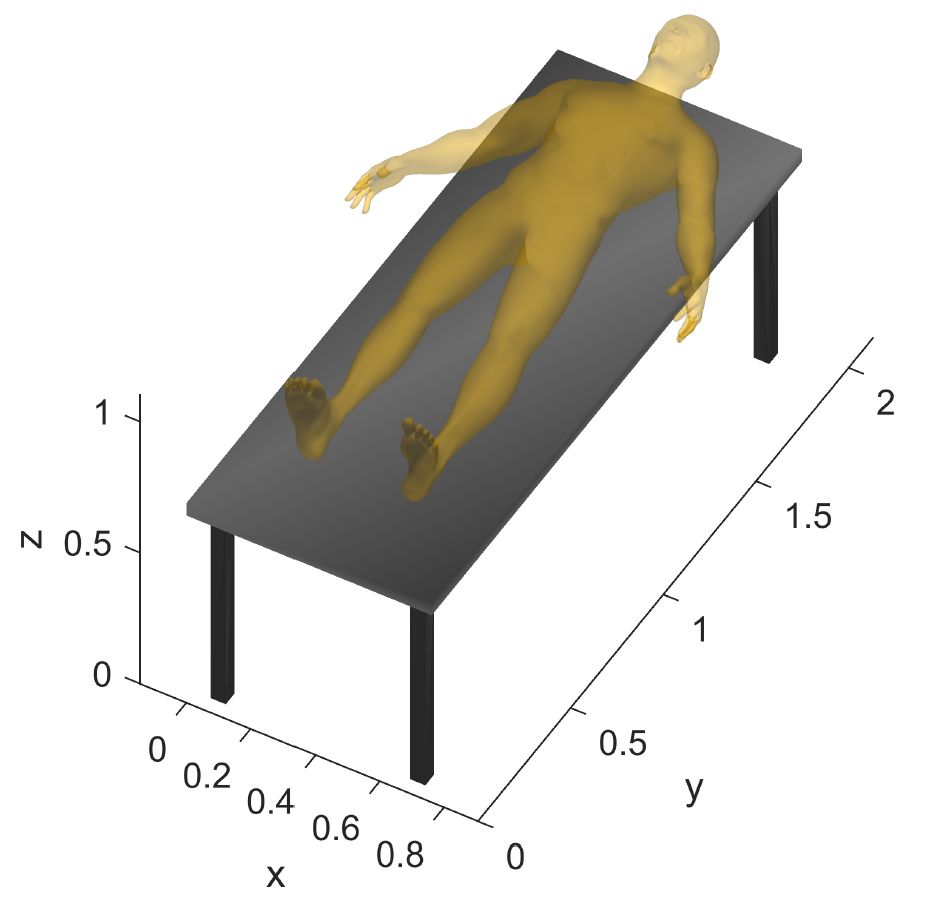

## put your code Here

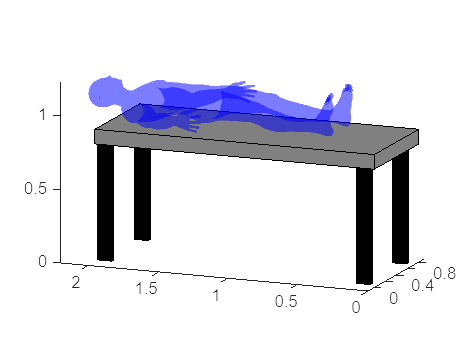

load('F_V_HumanBody.mat');
Vh(:,4) = 1;
Vh = Vh';
% We add a little offset between the man and the table to avoid z-fighting
T_human_mesa = transl(0,0,board_thickness+0.00001)*trotx(-pi/2)*transl(board_width/2, -max(Vh(2, :)), 2.2-max(Vh(3, :)));
T_U_H =T_mesa_U*T_human_mesa;
Vh = T_U_H*Vh;
Vh = Vh';
patch('Vertices',Vh(:,1:3),...
    'Faces',Fh,...
    'FaceColor',['b'],...
    'FaceAlpha',0.3,...
    'Linestyle','none');

### Fiducials

The Radiology Department before to take a Computer Tomography (CT) of the brain, fix three fiducials in the head of the patient for registering purpose,  visit: [https://en.wikipedia.org/wiki/Fiducial](https://en.wikipedia.org/wiki/Fiducial)

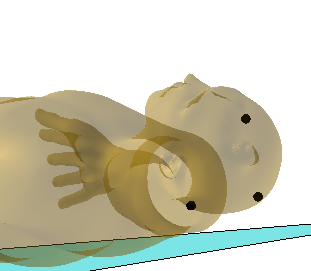

### Dicom image vs Image Reference frame {I}

Get familiar with Dicom Images, Visit: https://www.imaios.com/en/Imaios-Dicom-Viewer#!

Use a container Box of the skull  to infer the Image Reference Frame {I}

See:  6_Plot_Box_Cone.mlx and 7_Help_Image_RF_Containig_Box.fig to inspire yourselt 

**Expected results**

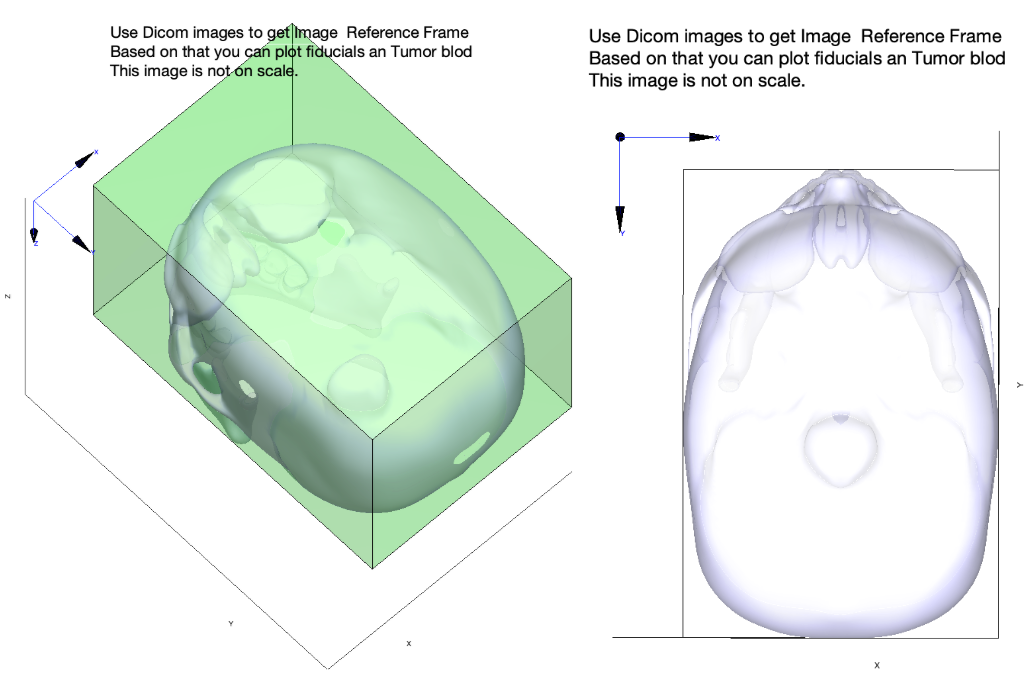

## put your code Here

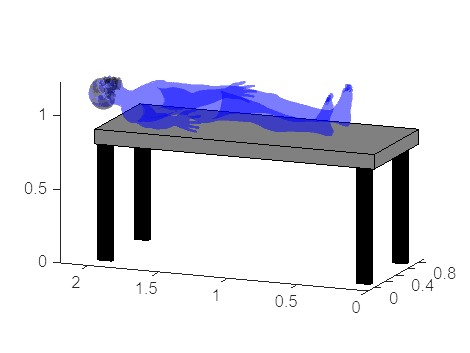

load('F_V_Skull.mat');
Vs(:,4) = 1;

% Skull reference frame with translation and rotation
S_U_ref = transl(0.4,1.98,0.25)*trotx(-90,'deg');

S_U_ref = T_mesa_U *S_U_ref;
% Patch skull with new vertices
Vs = (S_U_ref* Vs')';
patch('Vertices',Vs(:,1:3),...
    'Faces',Fs,...
    'FaceColor','black',...
    'FaceAlpha',0.3,...
    'Linestyle','none');

% Max and min dichotomy with y and z changed to change axis
maxDichotomy  = [206 1 236];
minDichotomy  = [43 112 25];
min(Vs(:,2))

ans = 1.9804

max(Vs(:,2))

ans = 2.1927

% Containing box min and max point (notice that y (which is the new z) is inverted)
minSkullSpace = [min(Vs(:,1)) max(Vs(:,2))            min(Vs(:,3))];
% We do not want the lower part of the skull so we start a little over the
% lowest point (by eye)
maxSkullSpace = [max(Vs(:,1)) min(Vs(:,2))+0.06  max(Vs(:,3))];

% Relation between dichotomy and matlab coordinates
dichotomy2Space = abs((maxSkullSpace-minSkullSpace)./(maxDichotomy-minDichotomy));

% Calculate the position of the image reference frame
referenceFrameSkullOrigin = maxSkullSpace + minDichotomy.*dichotomy2Space;

% Compute the image referenc frame with tranlations and rotations
I_U_ref = transl(referenceFrameSkullOrigin)*trotx(pi/2)*trotz(pi);

### Fiducials wrt {I}

Use the Dicom images to place the fiducial relative to Image Reference Frame {I}.

See: 5_Skull_pose_estimation.mlx and use the skull to make the exercise.

**Expected results**

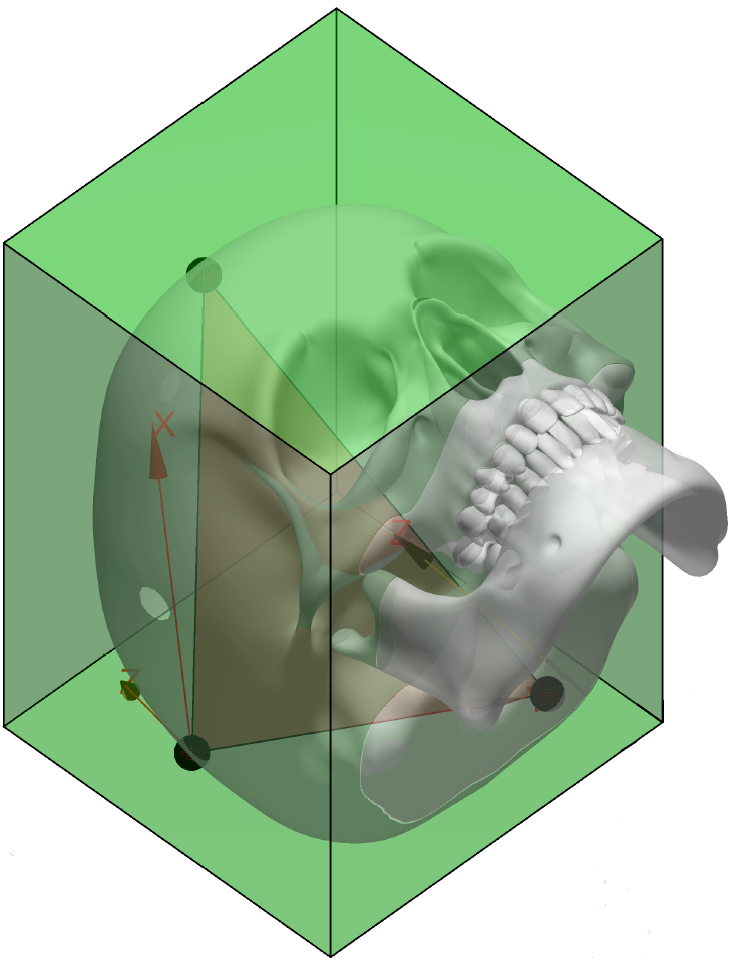

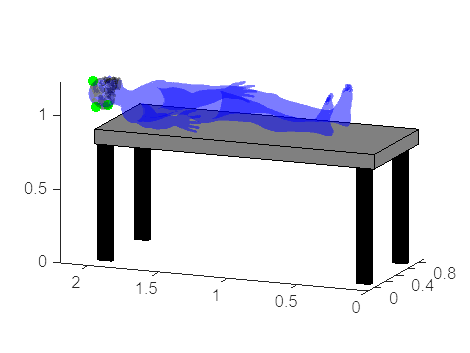

% We set by hand (using dicom viewer) the fiducial coordinates
fiducial1Coord = [70 214 32];
fiducial2Coord = [186 210 65];
fiducial3Coord = [122 62 94];

% Transformation matrix that transforms points from dichotomy to univers
d2s = [1 0 0 0; 0 0 1 0; 0 1 0 0; 0 0 0 1]*...
      diag([dichotomy2Space 1])*...
      [1 0 0 0; 0 0 -1 112; 0 1 0 0; 0 0 0 1];

% Compute and patch the 3 fiducials
fiducial1Space = I_U_ref*d2s*[fiducial1Coord 1]';
scatter3(fiducial1Space(1),fiducial1Space(2),fiducial1Space(3),'green','filled');
fiducial2Space = I_U_ref*d2s*[fiducial2Coord 1]';
scatter3(fiducial2Space(1),fiducial2Space(2),fiducial2Space(3),'green','filled');
fiducial3Space = I_U_ref*d2s*[fiducial3Coord 1]';
scatter3(fiducial3Space(1),fiducial3Space(2),fiducial3Space(3),'green','filled');

### Tumor points wrt {I}

Use the Dicom images to get the points of the outer perimeter of the tumor relative to Image Reference Frame {I}.

You can simplify the tumor information by defining the center of mass and estimate an equivalent diameter.

**Expected results**

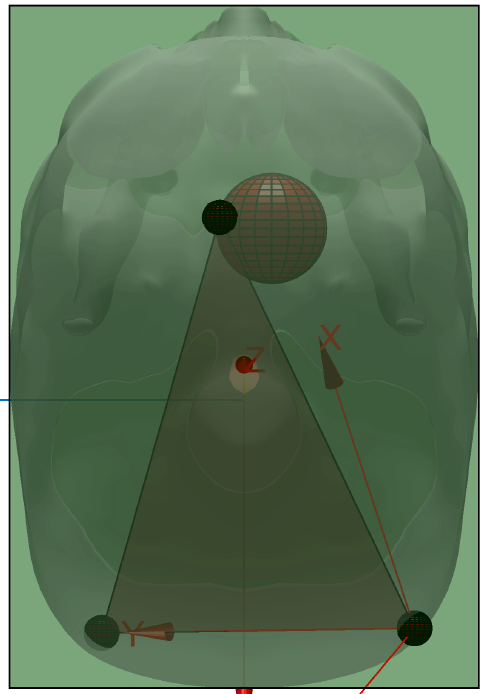

% Dichotomy tumor center coordinates
tumorCenterCoords = [132 98 77];

% Tumor radius in mm
tumorRadius = 0.016;

### Fiducials and Tumor wrt Human Reference Frame

Place fiducial and tumor in the head of the human. You will have to re-do the containing box secction.

**Expected results**

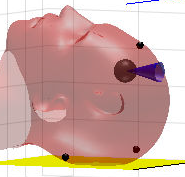

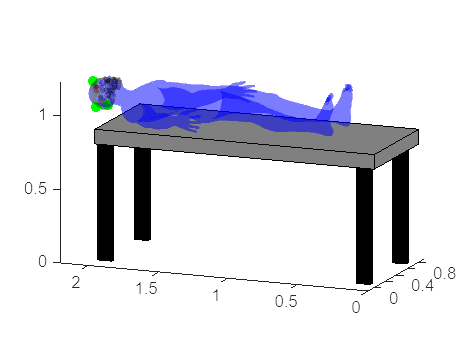

% Tumor center position in univers
tumorCenterUnivers = I_U_ref*d2s*[tumorCenterCoords 1]';

% Plot tumor as sphere
plot_sphere(tumorCenterUnivers,tumorRadius,[1 0 0],0.5);

## *First approach (10%)  *

*Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

### Robot manipulator

Consider  the best position of manipulator to be nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560. Use p560.teach to play.

Use: p560.base & p560.tool to locate the Puma and add the tools.

**Expected results**

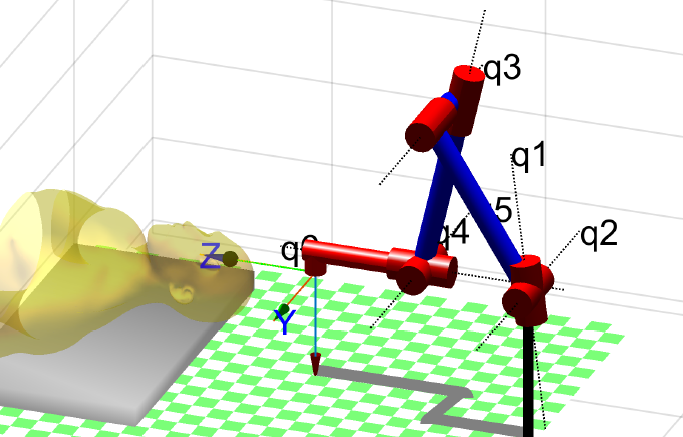

## put your code Here

mdl_puma560;
p560.base=transl(0.4, 2.6, 1)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (0.4, 2.6, 1), RPY/xyz = (0, 0, 0) deg              
 


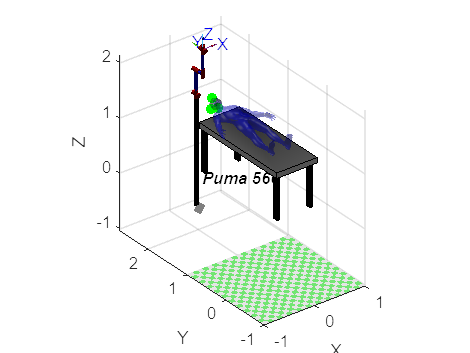

p560.plot(qr,'zoom',1.5)
T_R_U=p560.base.T;
hold on
axis equal;

### Reference Frames

Display all necessary reference frame. Use best scale to see it.

- {U} Univers [0 0 0]

- {R} Robot

- {I} Image

- {Tb} Table_body

- {Tt} Table tool

- {EE} End Efector

- others

- ...

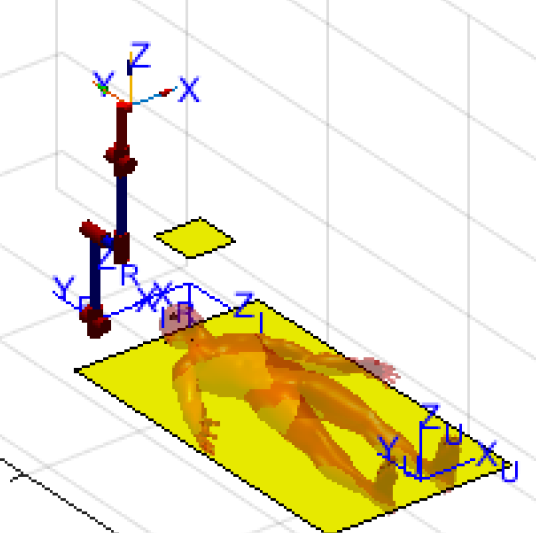

## put your code Here

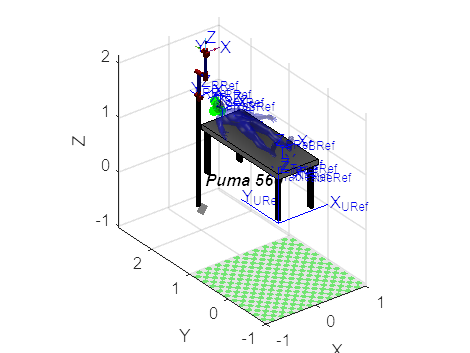

plotScale = diag([0.25, 0.25, 0.25, 1]);
trplot(eye(4)              , 'frame', 'URef'    );
trplot(T_mesa_U * plotScale, 'frame', 'TableRef');
trplot(T_U_H  * plotScale, 'frame', 'BRef'    );
trplot(S_U_ref  * plotScale, 'frame', 'SRef'    );
trplot(T_R_U  * plotScale, 'frame', 'RRef'    );
trplot(I_U_ref  * plotScale, 'frame', 'IRef'    );

### Transformations

Enumerate the transformation you will need.

## put your code Here

### Tumor points in Robot Frame.

Remember the Transform compound exercise

## *Second approach: ( 25%)*

Modify your code  to repeat the exercise if  the table with the patient is given as happend in the Rosa video.

To know the head relative pose with respect to the Puma Robot ...

clear
clf
close all

% Open the new starting figure
pat = open('3_Second_approach_Patient_pose.fig')

pat =   Figure (1: Figure) with properties:

      Number: 1
        Name: 'Figure'
       Color: [1 1 1]
    Position: [306.6000 -18.2000 1.1936e+03 775.2000]
       Units: 'pixels'

  Show all properties


patient = openfig('3_Second_approach_Patient_pose.fig','visible')

patient =   Figure (24: Figure) with properties:

      Number: 24
        Name: 'Figure'
       Color: [1 1 1]
    Position: [306.6000 -22.2000 1.1936e+03 775.2000]
       Units: 'pixels'

  Show all properties


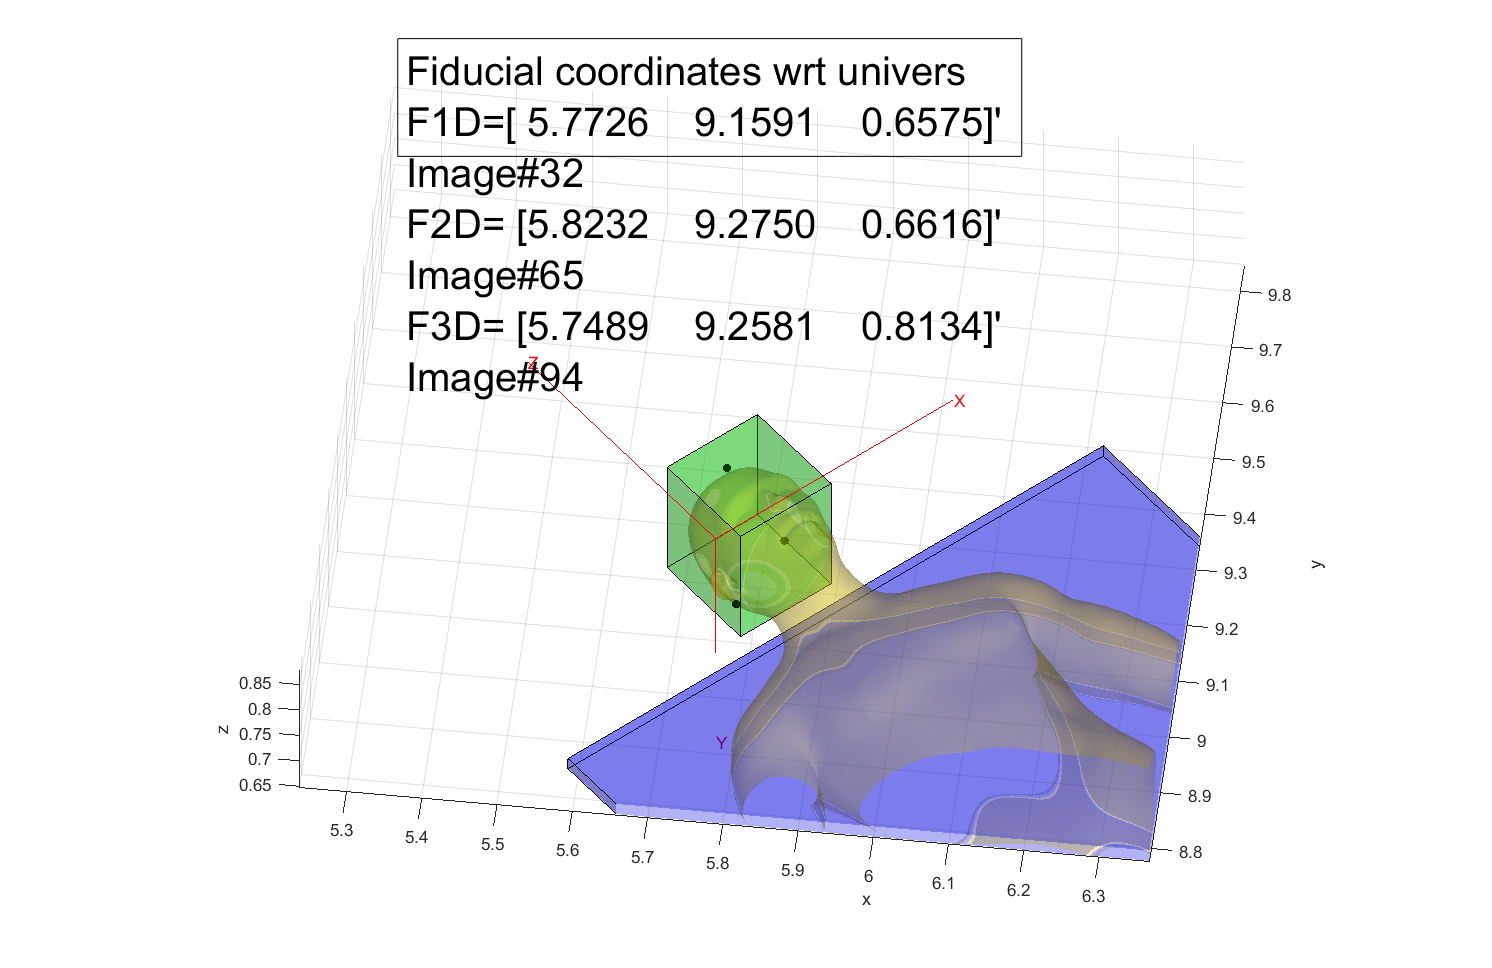

hold on

mdl_puma560;
p560.base=transl(5.75,9.75,0.5)*trotz(-pi/4);
p560.plot(qr,'zoom',1.5)
axis([5 6.5 8.8 10 0 1.8])
T_R_U=p560.base.T

T_R_U =     0.7071    0.7071         0    5.7500
   -0.7071    0.7071         0    9.7500
         0         0    1.0000    0.5000
         0         0         0    1.0000



F123=open ('Fiducial_U.mat');
F1= F123.F1;
F2= F123.F2;
F3= F123.F3;

Fi_R=inv(T_R_U)*[F1 F2 F3;ones(1,3)]

Fi_R =     0.4338    0.3876    0.3470
   -0.4018   -0.2841   -0.3486
    0.1575    0.1616    0.3134
    1.0000    1.0000    1.0000



Yf = (Fi_R(1:3,2)-Fi_R(1:3,1))/norm(Fi_R(1:3,2)-Fi_R(1:3,1));
b=(Fi_R(1:3,3)-Fi_R(1:3,1))/norm(Fi_R(1:3,3)-Fi_R(1:3,1));
Zf = cross(Yf,b)/norm(cross(Yf,b));
Xf = cross(Yf,Zf)/norm(cross(Yf,Zf));

T_F_R = [[Xf;0] [Yf;0] [Zf;0] [Fi_R(:,1)]]

T_F_R =     0.3353   -0.3652    0.8684    0.4338
    0.1638    0.9304    0.3280   -0.4018
   -0.9278    0.0323    0.3718    0.1575
         0         0         0    1.0000



T_F_U=T_R_U*T_F_R

T_F_U =     0.3529    0.3996    0.8460    5.7726
   -0.1213    0.9161   -0.3822    9.1591
   -0.9278    0.0323    0.3718    0.6575
         0         0         0    1.0000


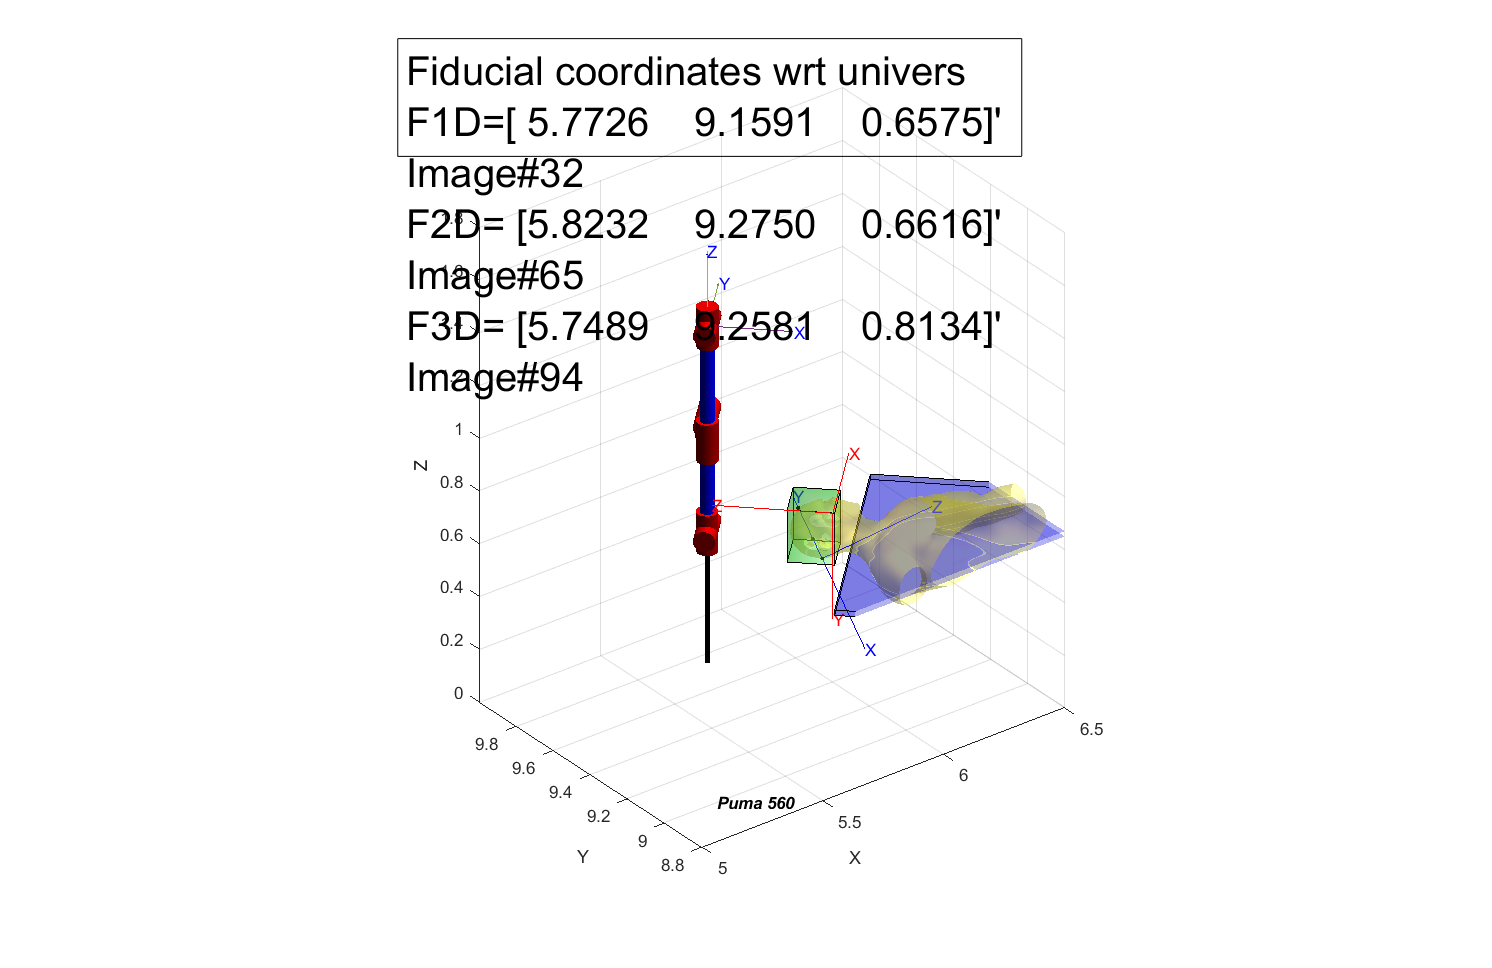

trplot(T_F_U,'Frame','F','color', 'b','length',0.4)


RPY=tr2rpy(T_F_R,'zyx')

RPY =     0.0865    1.1884    0.4544


T_F1_U=T_R_U*transl(Fi_R(1:3,1))*trotz(RPY(3))*troty(RPY(2))*trotx(RPY(1))

T_F1_U =     0.3529    0.3996    0.8460    5.7726
   -0.1213    0.9161   -0.3822    9.1591
   -0.9278    0.0323    0.3718    0.6575
         0         0         0    1.0000


T_F_U

T_F_U =     0.3529    0.3996    0.8460    5.7726
   -0.1213    0.9161   -0.3822    9.1591
   -0.9278    0.0323    0.3718    0.6575
         0         0         0    1.0000



pitch =1.4; % Pitch among slices 
F1D = [0.06973 0.21496 0.032*pitch]'; %image #32
F2D = [0.18743 0.21088 0.065*pitch]'; %image #65
F3D = [0.12295 0.05915 0.094*pitch]'; %image #94
Tumor=[0.13400 0.09600 0.078*pitch]';%image #78

[X,Y,Z] = sphere;
r = 0.005; % radius of the sphere
X2 = X * r;
Y2 = Y * r;
Z2 = Z * r; 

YfD = (F2D-F1D)/norm(F2D-F1D);
bD = (F3D-F1D)/norm(F3D-F1D);
ZfD = cross(YfD,bD)/norm(cross(YfD,bD));
XfD = cross(YfD,ZfD)/norm(cross(YfD,ZfD));

T_F_I = [[XfD;0] [YfD;0] [ZfD;0] [F1D;1]];

RPY=tr2rpy(T_F_I,'zyx');
T_F_U2=transl(F1D)*trotz(RPY(3))*troty(RPY(2))*trotx(RPY(1));

T_I_U=T_F_U*inv(T_F_I);
% Our Universe has y and z swapped
% We grab the rotational component of T_I_U and correct the axis, since we
% have y and z swapped with respect to Antonio's script, this matrix
% however, will not go from Image space to universe space by itself unlike
% the name suggests
T_I_U2= [[t2r(T_I_U) [0;0;0]]; [0 0 0 1]]*trotx(90,'deg')*trotz(180,'deg'); % 90 180

T_I_R=inv(T_R_U)*T_F_U*inv(T_F_I)

T_I_R =     0.0000    0.0000   -1.0000    0.4786
    1.0000    0.0000    0.0000   -0.4716
    0.0000   -1.0000   -0.0000    0.3725
         0         0         0    1.0000



Fi_R2=T_I_R*[[F1D F2D F3D];ones(1,3)]

Fi_R2 =     0.4338    0.3876    0.3470
   -0.4018   -0.2841   -0.3486
    0.1575    0.1616    0.3133
    1.0000    1.0000    1.0000


Fi_R

Fi_R =     0.4338    0.3876    0.3470
   -0.4018   -0.2841   -0.3486
    0.1575    0.1616    0.3134
    1.0000    1.0000    1.0000



Fi_R2=T_R_U*T_I_R*[[F1D F2D F3D];ones(1,3)]

Fi_R2 =     5.7726    5.8232    5.7489
    9.1591    9.2750    9.2581
    0.6575    0.6616    0.8134
    1.0000    1.0000    1.0000


Tumor

Tumor =     0.1340
    0.0960
    0.1092


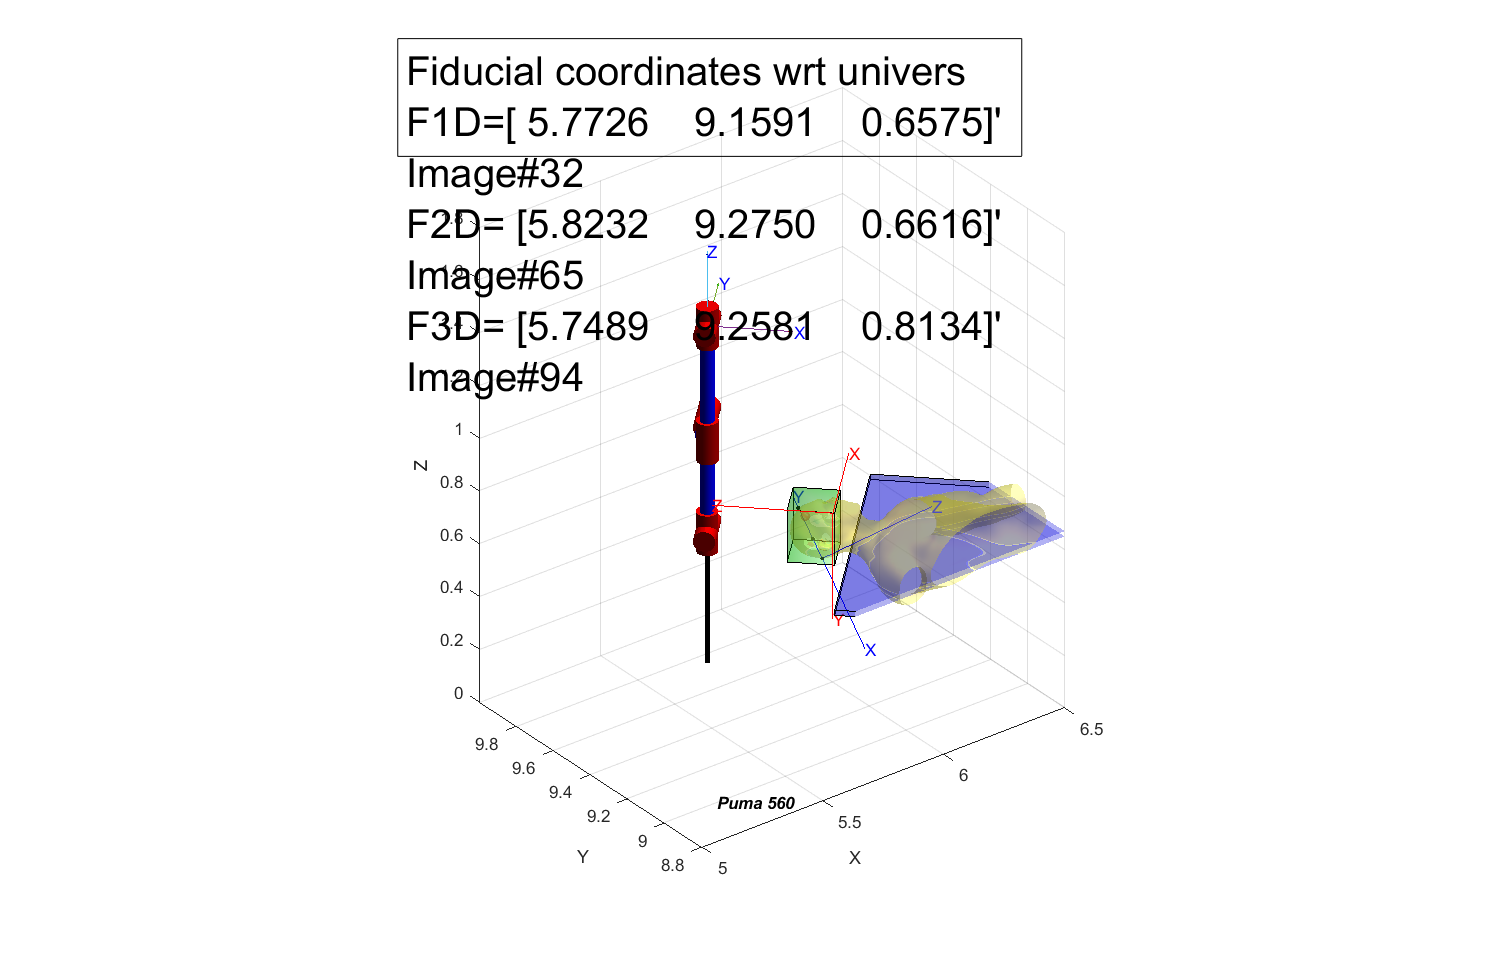

tumorPosition2A = T_I_U*[Tumor ;1];

% Plot the tumor
% Tumor radius in mm
hold on
tumorRadius = 0.016;
plot_sphere(tumorPosition2A(1:3),tumorRadius,[1 0 0],0.3);

 
% Tool definition
p560.tool = transl(0.05, 0, 0.25);

## Surgery (55%)

### Biospy

Prepare a script that perform a biopsy. Zoom in the scene and record a video with the best view.

Take into account:

- Use a tool that has the following Transformation: transl(0.05 0 0.25)

- Use 'trail' option of plot to visualize the trajectory.

- The speed of biopsy function that you design ought to be a parameter to satisfy the surgeons.

Answer these questions:

- Display in a figure the displacement, velocity and aceleration of the tool i End Efector Reference frame.

- How much enter the tool in the patient brain.

- What are the speed of the tool in Wordl Reference Frame.

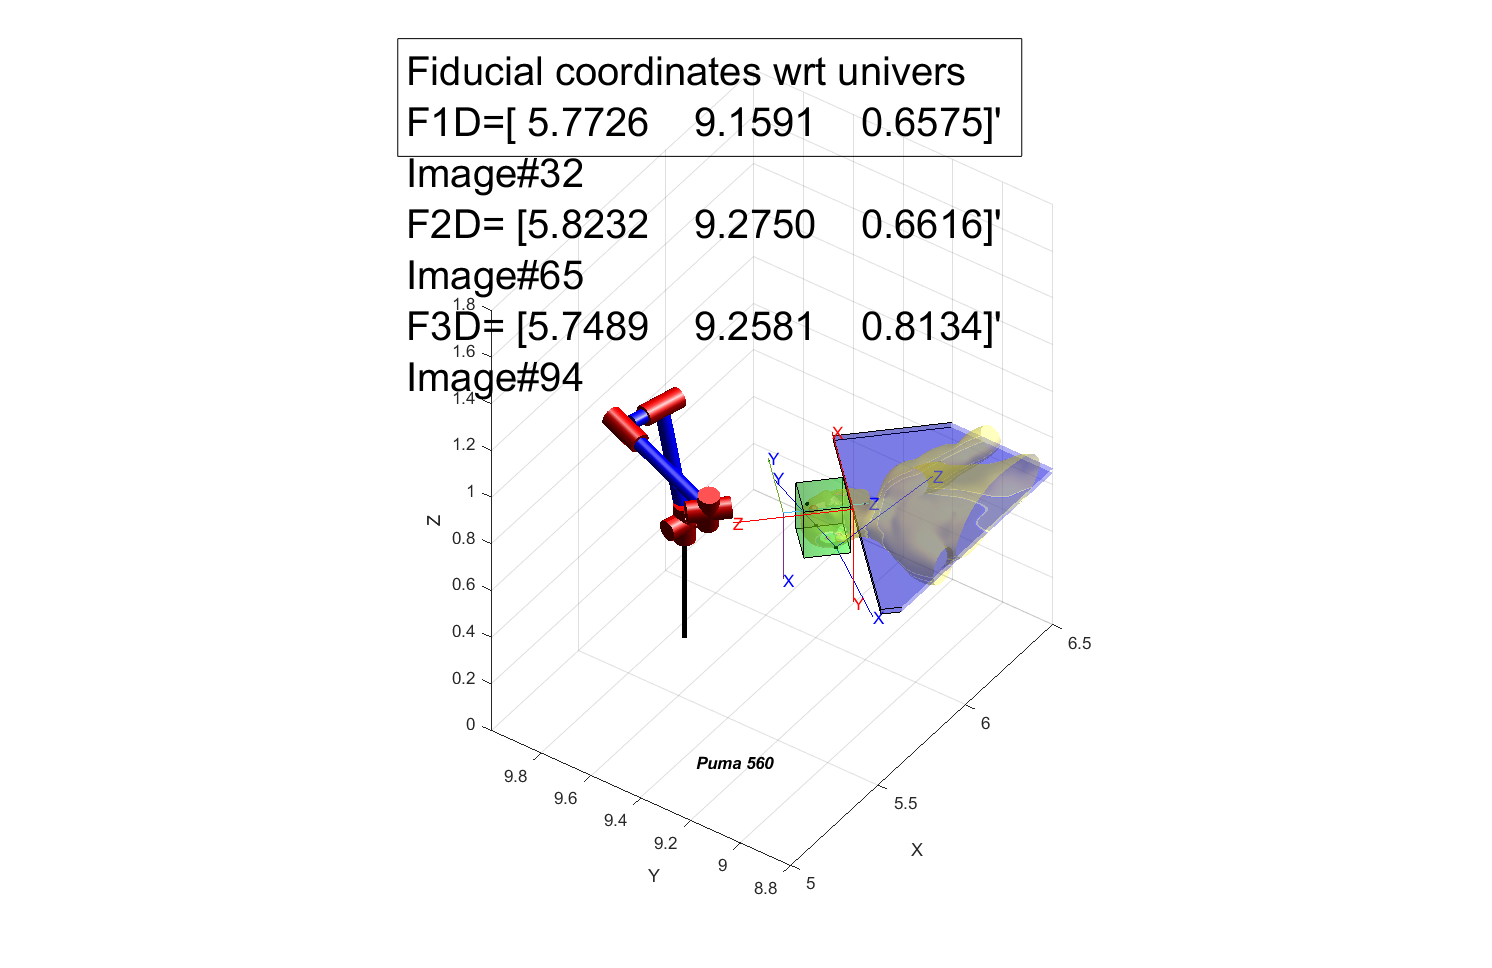

% Whether to Make videos or just plot the animation (both should not be
% true)
makeVideo = false;
plotAnimation = true;

% Calculate the tumor reference frame and the initial position of it.
tumorReference2A = transl(tumorPosition2A(1:3))*T_I_U2...
    *trotz(90,'deg')*troty(90,'deg');
initRobotFrame2A = transl(tumorPosition2A(1:3))*...
    T_I_U2*transl([0 -0.1 0])*trotz(90,'deg')*troty(90,'deg');

% Define approach and recede trajectories
steps= 40;
t = tpoly(0,1,steps);
approach2A = ctraj(initRobotFrame2A, tumorReference2A, t);
recede2A = ctraj(tumorReference2A, initRobotFrame2A, t);
trajPoints = cat(3,approach2A,recede2A);
% combine approach and recede

% Debug plot
% for i = 1:steps
%     trplot(trajPoints(:,:,i), 'length',0.2)
% end

trajectory = p560.ikine6s(trajPoints,'run');
 
% Plot results
if plotAnimation
    p560.plot(trajectory,'zoom',2.5,'workspace',[3 4 2.4 3.5 1 1.7],...
     'view',[-55 40],'trail', {'r', 'LineWidth', 1.5} );
end

% Movie
if makeVideo
    p560.plot(trajectory,'zoom',2.5,'movie','Videos/Biopsy2A.mp4','workspace',...
     [3 4 2.4 3.5 1 1.7],'fps',40,'trail',"-",'jaxes','view',[-45 40]);
end

% get the handle to the current figure
fig = gcf;

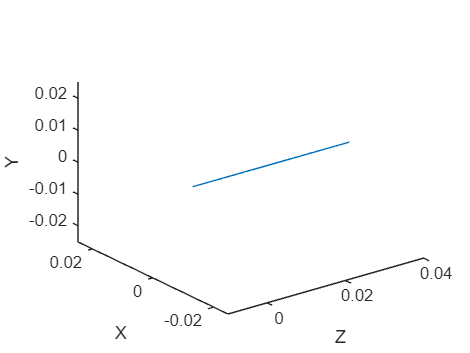

%We calculate every position from the EE reference frame
TProf = zeros(steps*2,4);
for i=1:steps*2
%     TProf(i,:) = inv(trajPoints(:,:,1)) * [transl(trajPoints(:,:,i)); 1];
    TProf(i,:) = trajPoints(:,:,1) \ [transl(trajPoints(:,:,i)); 1];
end
figure
%trajectory position from EE_RF
plot3(TProf(:,3), TProf(:,1), TProf(:,2))
xlabel('Z')
ylabel('X')
zlabel('Y')
axis([-0.01 0.04 -0.025 0.025 -0.025 0.025])

% How much enter the tool in the patient brain
% Define trepanation hole center and frame
trepanationHoleCenter2A = T_I_U*[Tumor(1:2)' 0.15 1]'

trepanationHoleCenter2A =     5.7437
    9.2789
    0.7765
    1.0000


% Distance from the tumor to the center of the biopsy/trepanation hole
vdist = trepanationHoleCenter2A-tumorPosition2A

vdist =    -0.0288
    0.0288
   -0.0000
         0


dist = norm(vdist) % magnitude of the distance

dist = 0.0408

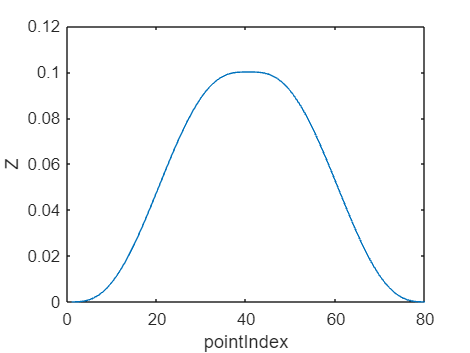

%Z_EE over time
figure
plot(1:steps*2, TProf(:,3))
xlabel('pointIndex')
ylabel('Z')

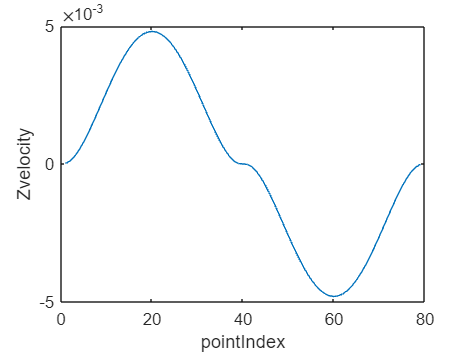

%Z_EE velocity over time 
figure
plot(1:steps*2-1, diff(TProf(:,3)))
xlabel('pointIndex')
ylabel('Zvelocity')

% Get back focus onto patient
figure(fig)

### Trepanation

Prepare a script that perform trepanation. Zoom in the scene and record a video with the best view.

Take into account:

- Use a tool that has the following Transformation: transl(0 0 0.2)

- Use 'trail' option of plot to visualize the trajectory.

- Place a 45º cone on top of the trepanation to better understand. 

- See: 6_Plot_Box_Cone_fiducials.mlx. You will have to scale it. Play with transparency.

Answer these questions:

- Display in a figure the lineal displacement, velocity and aceleration of the tool in End Efector Reference frame.

- Display in a figure the manipulabitlity of the trepanation function either for translation and rotation.

- Find an alternate robot location for improving your manipulabitity.

% Tool definition
p560.tool = transl(0, 0, 0.2);
% Define new radius
newSmallRadius = tumorRadius-0.001;
% Define trepanation hole center and frame
trepanationHoleCenter2A = T_I_U*[Tumor(1:2)' 0.15 1]'

trepanationHoleCenter2A =     5.7437
    9.2789
    0.7765
    1.0000


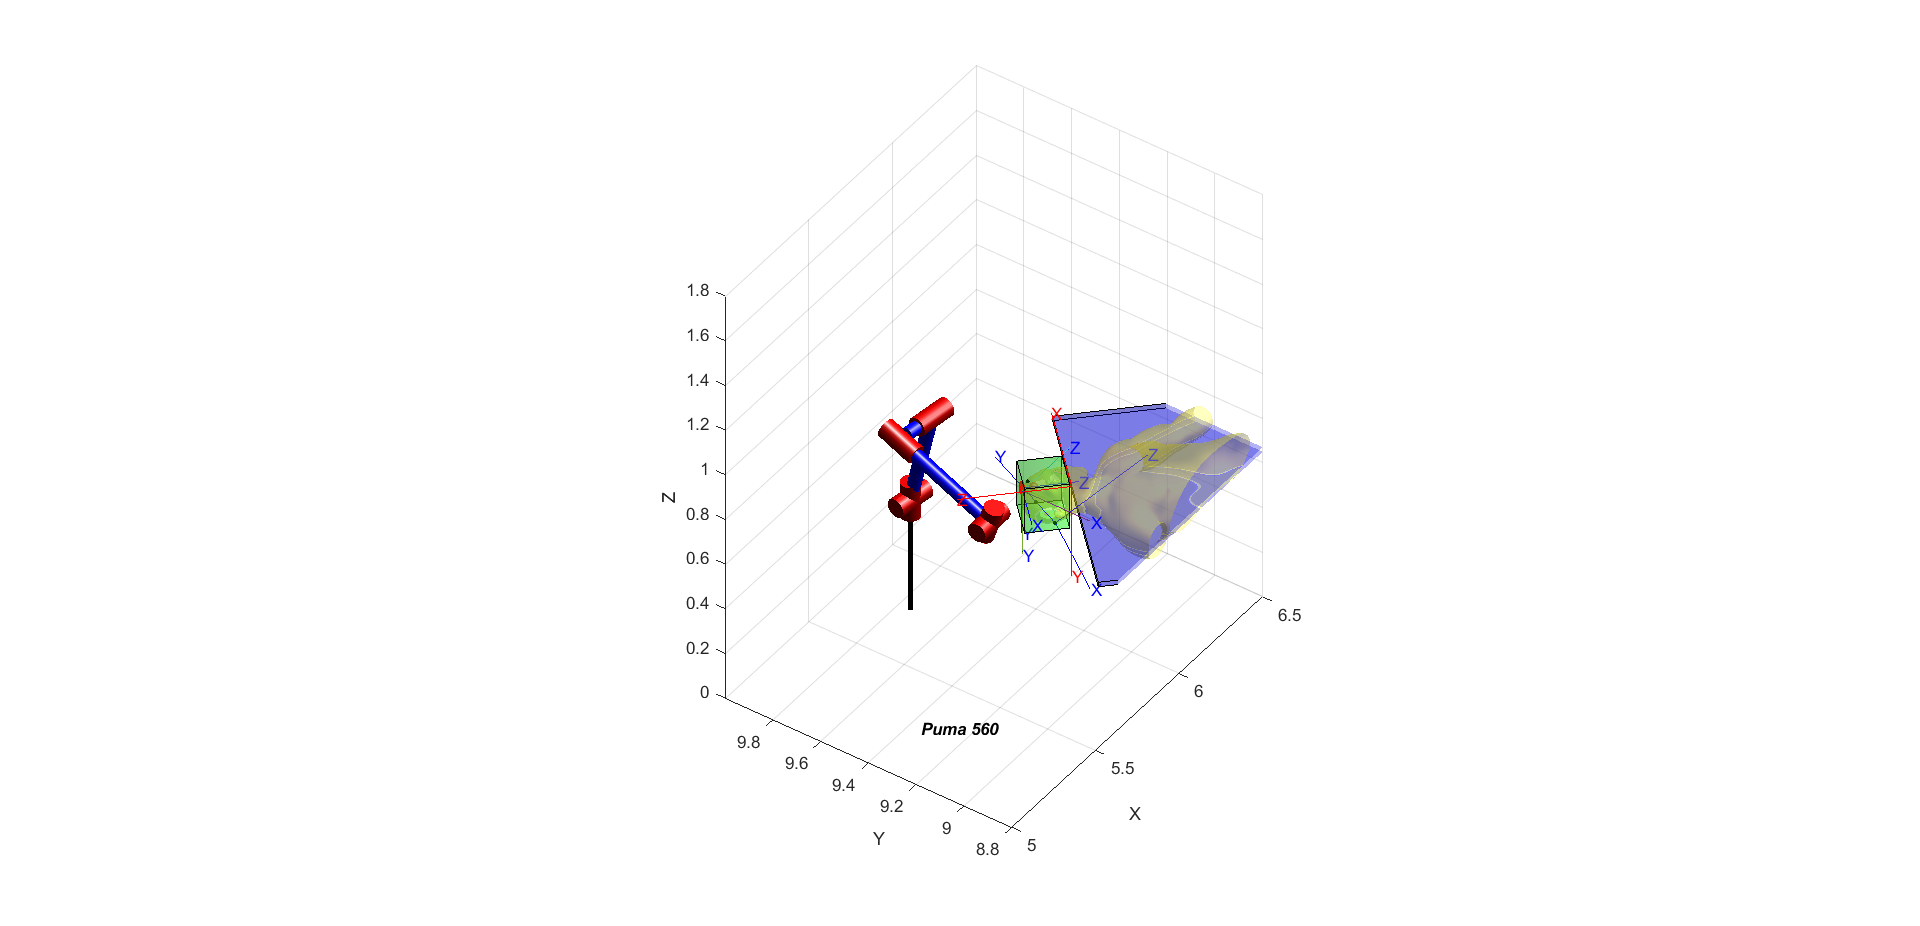

trepanationHoleFrame2A = transl(trepanationHoleCenter2A(1:3))*T_I_U2*...
 trotx(-90,'deg');
trplot(trepanationHoleFrame2A, 'length',0.2)

% Calculate the trepanation poses
steps = 100;
Trep_Pose2A = zeros(4,4,steps); % preallocate
for i=1:steps
 Trep_Pose2A(:,:,i)= trepanationHoleFrame2A*trotz(2*pi*i/steps)*...
 transl(newSmallRadius, 0,0)*troty(-45,'deg');
end

% Draw the trepanation circle
cir=transl(Trep_Pose2A)';
hold on
plot3(cir(1,:), cir(2,:), cir(3,:),'r','LineWidth',3);

% Calculate the trajectory of the trepanation

trajectory2A = p560.ikine6s(Trep_Pose2A, 'run');

% Movie
if makeVideo
    p560.plot(trajectory2A,'trail','-','zoom',2.5,'movie',...
    'Videos/Trepanation2A.mp4','workspace',[3 4 2.4 3.5 1 1.7],'fps',30,'view',[-55 40])
end

% Plot
if plotAnimation
    p560.plot(trajectory2A,'trail','-','zoom',2.5,...
    'workspace',[-0.5 0.5 1 2.5 0.5 2],'view',[-55 40]);
end

% get the handle to the current figure
fig = gcf;

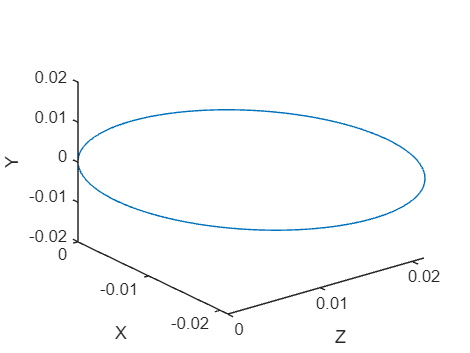

%We calculate every position from the EE reference frame
TProfT = zeros(steps,4);
for i=1:steps
%     TProfT(i,:) = inv(Trep_Pose2A(:,:,1)) * [transl(Trep_Pose2A(:,:,i)); 1];
    TProfT(i,:) = Trep_Pose2A(:,:,1) \ [transl(Trep_Pose2A(:,:,i)); 1];
end

figure
%trajectory position from EE_RF
plot3(TProfT(:,3), TProfT(:,1), TProfT(:,2))
xlabel('Z')
ylabel('X')
zlabel('Y')

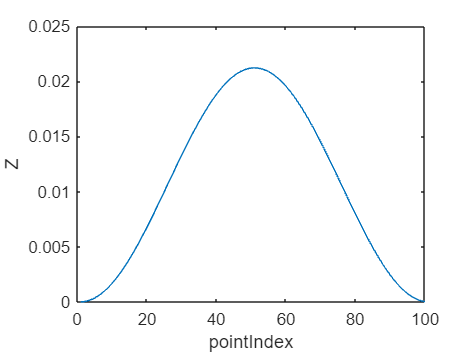

%Z_EE over time
figure
plot(1:steps, TProfT(:,3))
xlabel('pointIndex')
ylabel('Z')

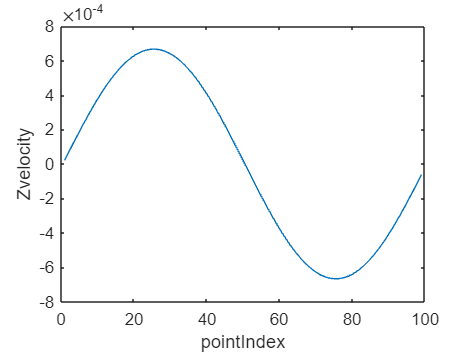

%Z_EE velocity over time 
figure
plot(1:steps-1, diff(TProfT(:,3)))
xlabel('pointIndex')
ylabel('Zvelocity')

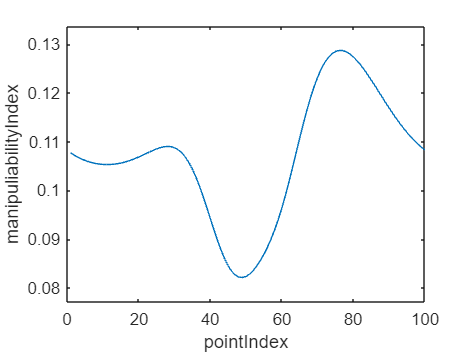

figure
manipulabilitiesT = p560.maniplty(trajectory2A,'trans');
manipulabilitiesR = p560.maniplty(trajectory2A,'rot');

%manipulability Trans
plot(1:steps, manipulabilitiesT)
xlabel('pointIndex')
ylabel('manipuliabilityIndex')
axis([0 steps min(manipulabilitiesT)-0.005 max(manipulabilitiesT)+0.005])

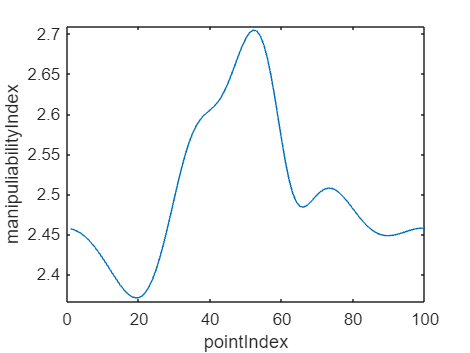

% %manipulability Rot
figure
plot(1:steps, manipulabilitiesR)
xlabel('pointIndex')
ylabel('manipuliabilityIndex')
axis([0 steps min(manipulabilitiesR)-0.005 max(manipulabilitiesR)+0.005])

figure
[minT, minIndexT] = min(manipulabilitiesT)

minT = 0.0821

minIndexT = 49

[minR, minIndexR] = min(manipulabilitiesR)

minR = 2.3703

minIndexR = 19


[maxT, maxIndexT] = max(manipulabilitiesT)

maxT = 0.1287

maxIndexT = 76

[maxR, maxIndexR] = max(manipulabilitiesR)

maxR = 2.7048

maxIndexR = 52


view(45,45)
p560.vellipse(trajectory2A(minIndexR,:), 'rot')
xlabel('X')
ylabel('Y')
zlabel('Z')

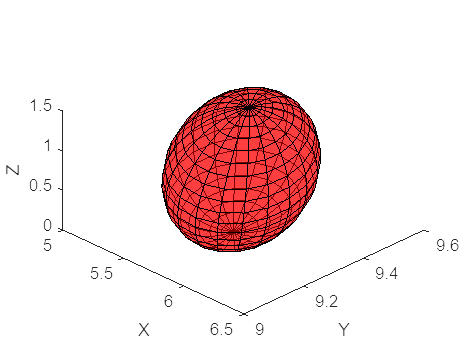

% there is a bug where the second ellipse will not show? But if you change
% the order in which you execute the rot and trans it shows them correctly
% and they are both pretty nicely shaped ellipsoids (meaning they are not
% too slanted)
figure
view(45,45)
p560.vellipse(trajectory2A(minIndexT,:), 'trans')

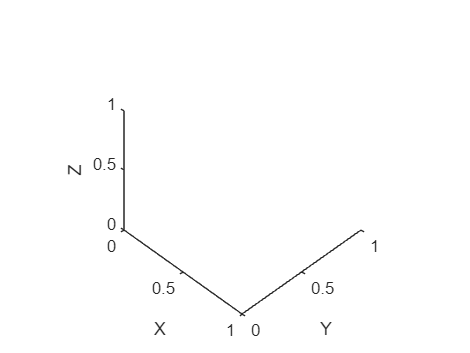

xlabel('X')
ylabel('Y')
zlabel('Z')
axis equal

% Get back focus onto patient
figure(fig)

### Tumor burning

Prepare a script that perform tumor burning with the laser.  Zoom in the scene and record a video with the best view.

You ought to think in an algorithm, that in order, fill up the tumor's  equivalent sphere with small burning spheres of 4mm diameter.

Use a tool that has the following Transformation: transl(0 0 0.2)

Answer these questions:

- Display in a figure the lineal displacement, velocity and aceleration of the tool in End Efector Reference frame.

- How long it takes your burning function to burn the tumor

% Tool definition
p560.tool = transl(0, 0, 0.2);

% Define burning points
topLayers = [ 0.005  0       0;...
              0.0025  0.0042  0;...
             -0.0025  0.0042  0;...
             -0.005  0       0;...
              0.0025  -0.0042 0;...
             -0.0025  -0.0042 0];

midLayers = [-0.010  0     0;...
             -0.008  0.005 0;...
             -0.004  0.010 0;...
              0.004  0.010 0;...
              0.008  0.005 0;...
              0.010  0     0;...
              0.008 -0.005 0;...
              0.004 -0.010 0;...
             -0.004 -0.010 0;...
             -0.008 -0.005 0;...
             -0.004  0     0;...
              0      0.005 0;...
              0.004  0     0;...
              0     -0.005 0];

midLayers(:,4) = 1;
layer2 = midLayers + [0 0  0.004 0];
layer3 = midLayers + [0 0 -0.004 0];
topLayers(:,4) = 1;
layer1 = topLayers + [0 0  0.0105 0];
layer4 = topLayers + [0 0 -0.0105 0];

% Combine all layers
allLayers = [layer1; layer2; layer3; layer4];
[rows,~] = size(allLayers)

rows = 40


% Draw the burning hole
holeSteps = 33;
cir2A = zeros(3,holeSteps);
for i=1:holeSteps
    cir2A(:,i)= transl(trepanationHoleFrame2A*trotz(2*pi*i/32)*...
        transl(tumorRadius/2, 0,0));
end
plot3(cir2A(1,:), cir2A(2,:), cir2A(3,:),'r','LineWidth',1);

% Time definition
t = [0:0.15:3]';

% Compute the initial and starting (from the burning) angles
initRobotPos2A = [0 0 0 0 0 0]

initRobotPos2A =      0     0     0     0     0     0


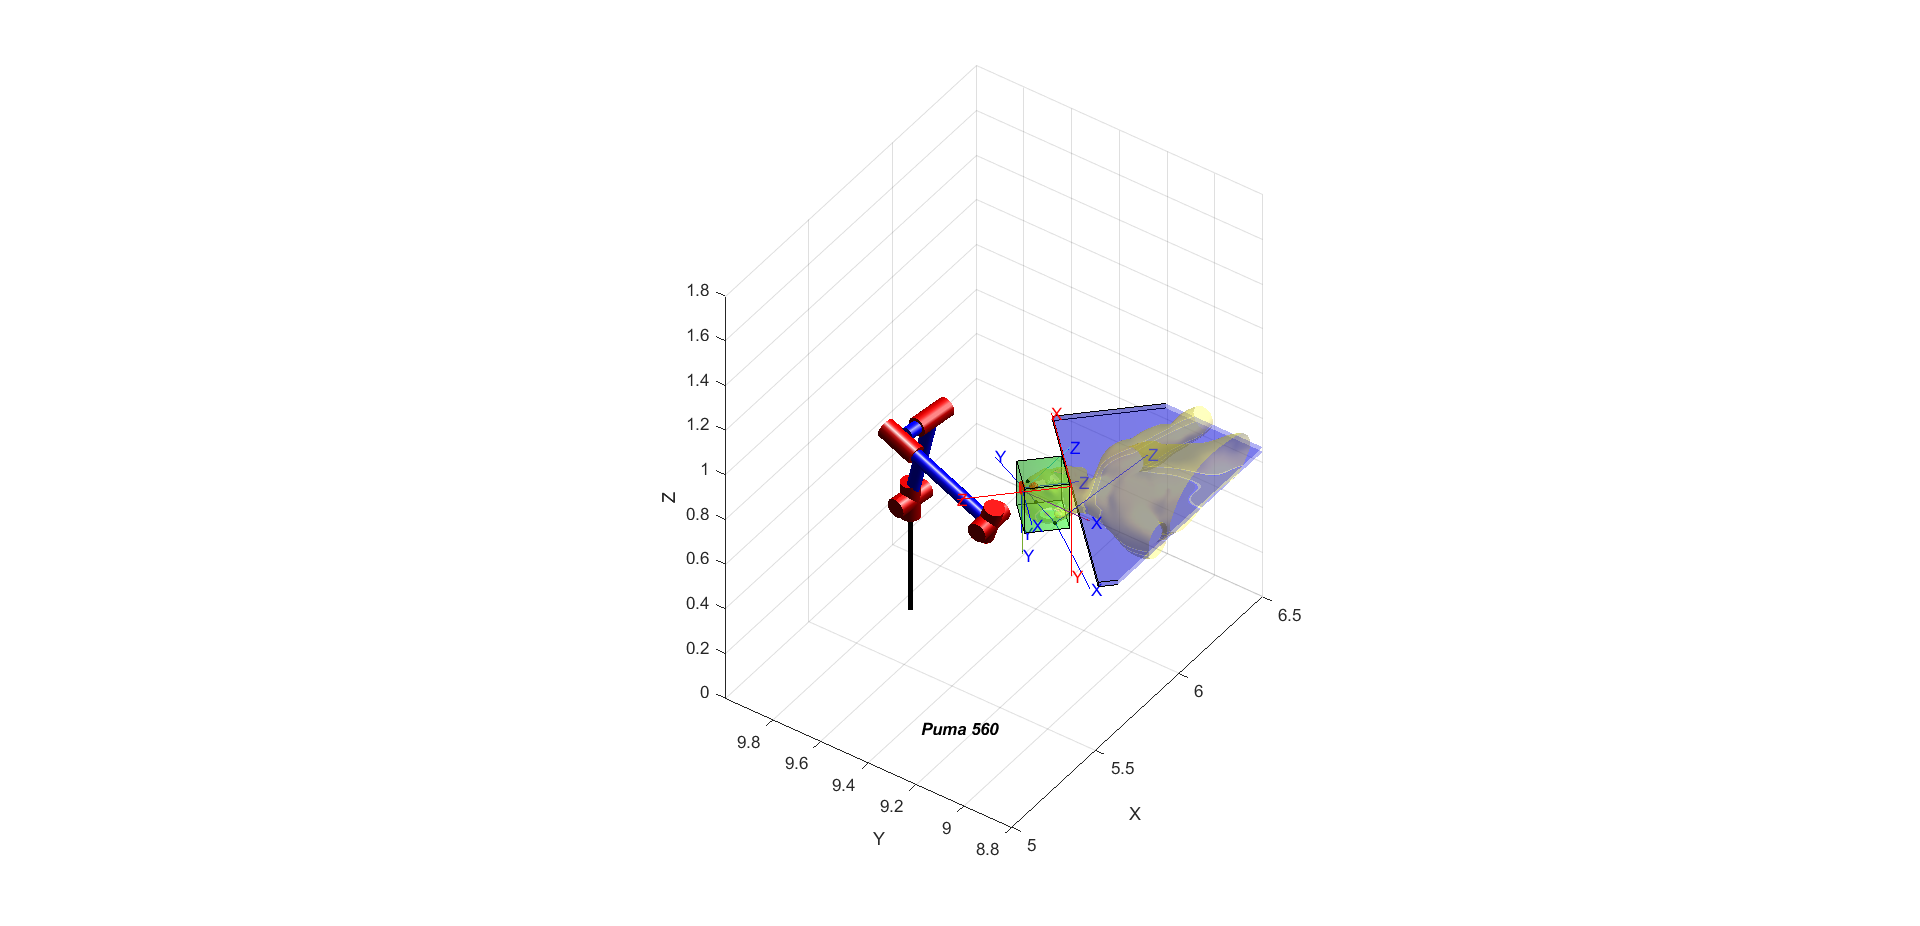

startingFrame2A = trepanationHoleFrame2A;
startingPos2A = p560.ikine6s(startingFrame2A,'run');

% Calculate all the burning poses and plot all the spheres
Burn_pose2A = zeros(4,4,rows); % preallocate for speed
points = zeros(rows,4); % preallocate for speed
for i=1:rows
    % Calculate the burning point in univers
    point = transl(tumorPosition2A(1:3))*T_I_U2*trotx(90,'deg')*...
    allLayers(i,:)'; %adaptar rotacions
    points(i,:) = point;

    % Plot the burning point
    plot_sphere(point,0.004,[1 0 0]);
    
    % Calculate the pose for this burning point
    point2 = inv(T_I_U2)*point;
    thcU = inv(T_I_U2)*trepanationHoleCenter2A;
    d = sqrt((thcU(3)-point2(3))^2+(thcU(1)-point2(1))^2);
    angleX = atan2(d,thcU(2)-point2(2));
    angleZ = atan2(thcU(1)-point2(1),thcU(3)-point2(3));
    Burn_pose2A(:,:,i) = transl(trepanationHoleCenter2A(1:3))*T_I_U2*...
        troty(angleZ)*trotx(angleX)*trotx(90,'deg');

end

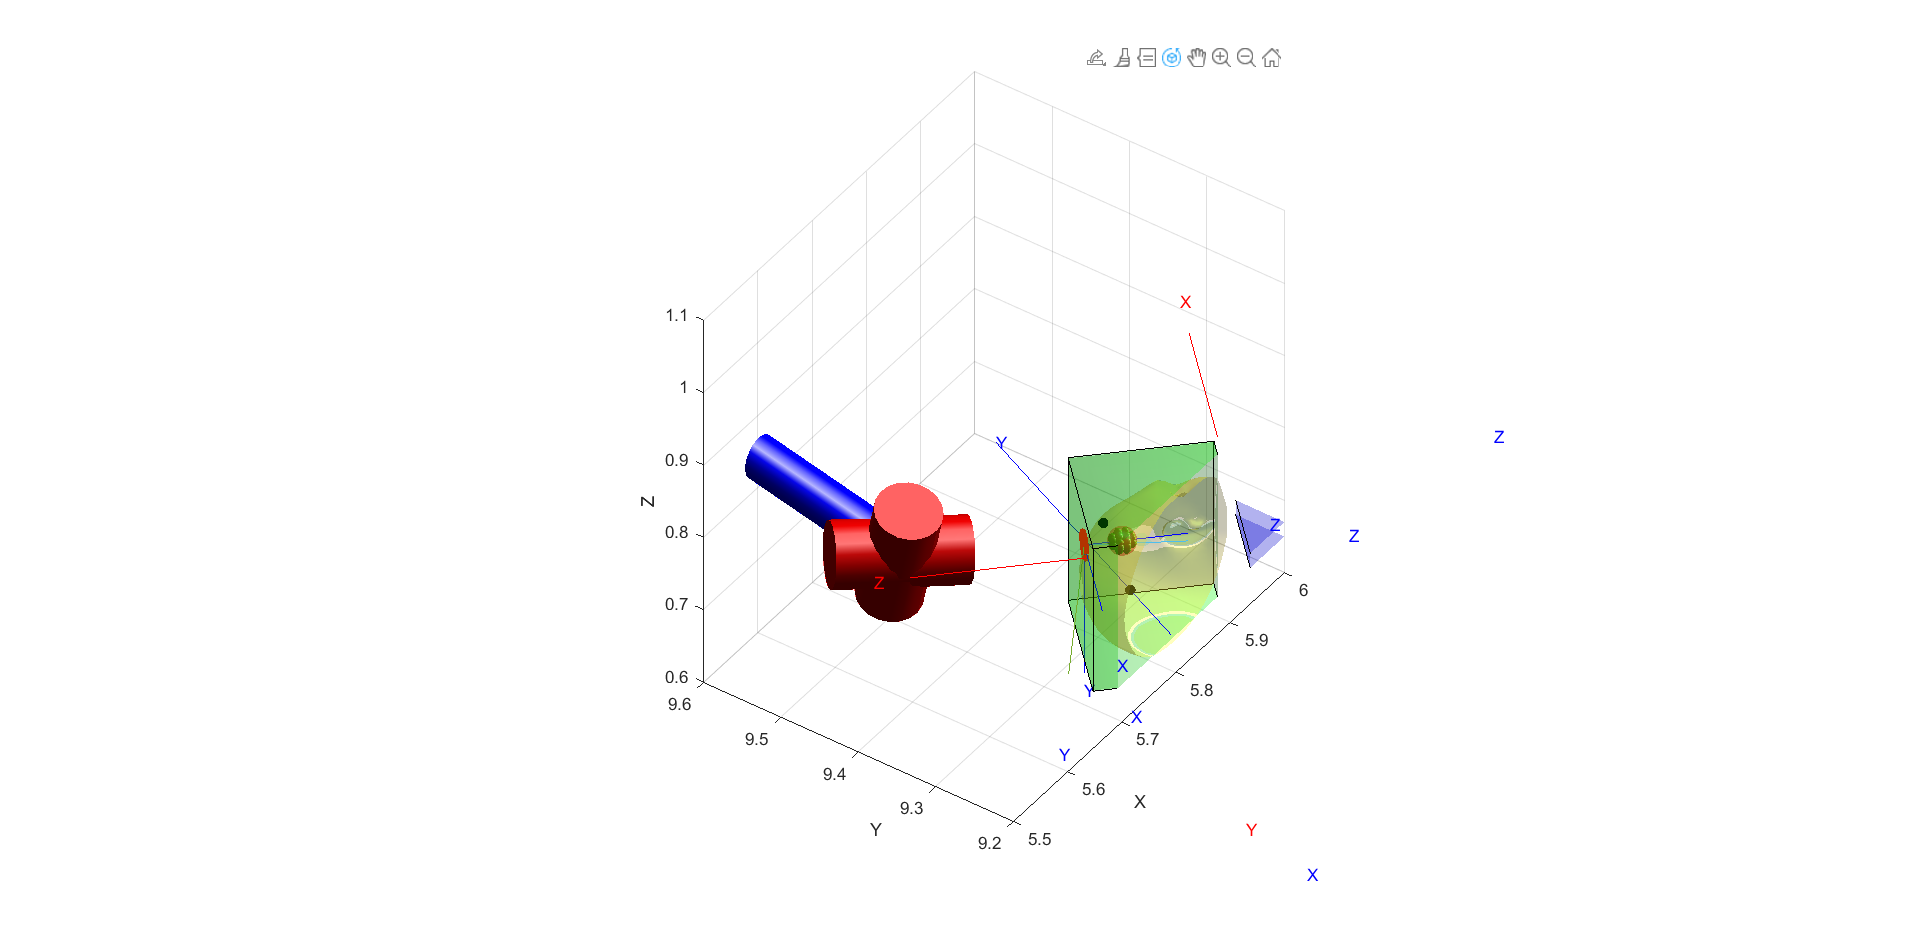

% Set zoom
xlim([5.5 6]); ylim([9.2 9.6]); zlim([0.6 1.1]);

% Compute the approaching trajectory with an aproximation point
aproximationPos = p560.ikine6s(startingFrame2A*transl(0,0,-0.1),'run');
initAprox = jtraj(initRobotPos2A, aproximationPos, [0:0.1:6]');
aproxStart = jtraj(aproximationPos, startingPos2A, [0:0.1:6]');

% Concatenate videos to create the burning video
if makeVideo 
    vidwriter = VideoWriter('Burning2A.mp4','MPEG-4');
    open(vidwriter)
end
t = [0:0.1:1]';
posePre = startingPos2A;
trajBurnPoints = ctraj(startingFrame2A, Burn_pose2A(:,:,1), t);
for i=1:rows
    % Compute the necessary trajectory to go to the next pose
    poseAct = p560.ikine6s(Burn_pose2A(:,:,i),'run');
    trajectory = jtraj(posePre, poseAct, t);
    
    if i~=1
        trajectoryBurn = ctraj(Burn_pose2A(:,:,i-1), Burn_pose2A(:,:,i), t);
        trajBurnPoints = cat(3,trajBurnPoints,trajectoryBurn);
    end

    % Do the movie for this trajectory and added to the final video
    if makeVideo
        p560.plot(trajectory,'movie',char("frames/auxiliar"+i+".mp4"),'trail','-',...
        'zoom',10,'workspace',[-0.5 0.5 1 2.5 0.5 2],'view',[-55 40]);
        iterationVideo = VideoReader(char("frames/auxiliar"+i+".mp4"));
        frames = read(iterationVideo,[1,Inf]);
        writeVideo(vidwriter, frames);
    end
    if plotAnimation
        p560.plot(trajectory,'trail','-','zoom',2.5,...
    'workspace',[-0.5 0.5 1 2.5 0.5 2],'view',[-55 40]);
    end

    % Draw the green sphere
    plot_sphere(points(i,1:3),0.0041,[0 1 0]);

    % Change previous pose
    posePre = poseAct;
end

if makeVideo
    close(vidwriter)
end

Time per burning point

% t is Nx1 array. So length(t) = N
timeBP = length(t)

timeBP = 11

Number of burning points

numberBP = rows;

Ablation frames

ablationFrames = timeBP*numberBP;

Frames per second used

fpsDefault = 30;

Ablation time in seconds

ablationTime = ablationFrames/fpsDefault;
resultingAblationTime = ablationTime

resultingAblationTime = 14.6667

The time is calculated for the video, in real time the time may vary from each execution and will probably take longer, since it has to calculate in real time.

% get the handle to the current figure
fig = gcf;

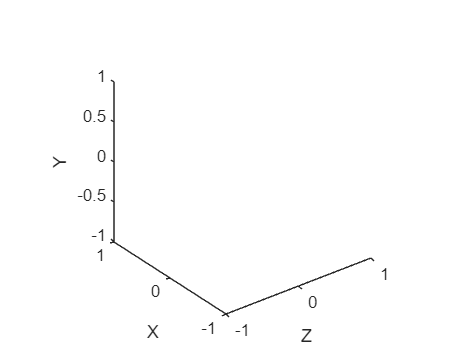

%We calculate every position from the EE reference frame
steps = length(t) * rows;
TProfB = zeros(steps, 4); % preallocate
for i=1:steps
%     TProfB(i,:) = inv(trajBurnPoints(:,:,1)) * [transl(trajBurnPoints(:,:,i)); 1];
    TProfB(i,:) = trajBurnPoints(:,:,1) \ [transl(trajBurnPoints(:,:,i)); 1];
end

figure
%trajectory position from EE_RF
plot3(TProfB(:,3), TProfB(:,1), TProfB(:,2))
xlabel('Z')
ylabel('X')
zlabel('Y')
axis equal

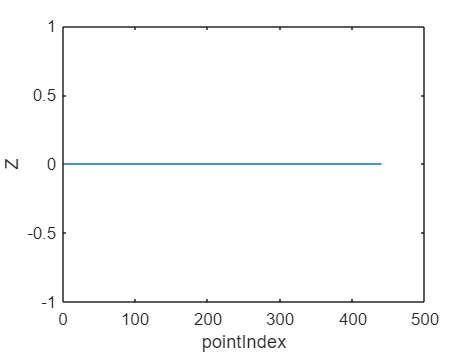

%Z_EE over time
figure
plot(1:steps, TProfB(:,3))
xlabel('pointIndex')
ylabel('Z')

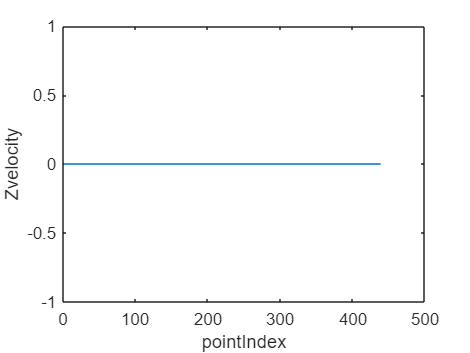

%Z_EE velocity over time 
figure
plot(1:steps-1, diff(TProfB(:,3)))
xlabel('pointIndex')
ylabel('Zvelocity')

As the End Effector is not really moving, just rotating as needed, it does not really have velocity nor acceleration and also there isn't any displacement.

% Get back focus onto patient
figure(fig)